clear; clc;
close all;

%% Text Size
set(0,'DefaultAxesFontsize',6);
set(0,'DefaultTextFontsize',6);

%% Text Fonts
set(0,'DefaultTextFontname','Arial');
set(0,'DefaultAxesFontname','Arial');

figsize = [10 15 5.3 3.5];
figpos = [0.18 0.25 0.75 0.65];
lw = 0.8;

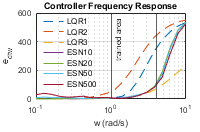

load("data\fig4_sinusoiderrordata.mat");

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');

% loglog(wlist, lqrsinerrorlist, '--');
s1 = semilogx(wlist, lqrsinerrorlist, '--');
s1(1).LineWidth = lw;
s1(2).LineWidth = lw;
s1(3).LineWidth = lw;
hold on;
% loglog(wlist, esnsinerrorlist);
s2 = semilogx(wlist, esnsinerrorlist);
s2(1).LineWidth = lw;
s2(2).LineWidth = lw;
s2(3).LineWidth = lw;
s2(4).LineWidth = lw;
hold on;
xline(1,'-','trained area', FontSize=6, FontName="Arial");
hold on;
xline(4);
grid on;
leg = legend(["LQR1" "LQR2" "LQR3" "ESN10" "ESN20" "ESN50" "ESN500"]);
leg.Box = "off";
leg.ItemTokenSize = [15 20];
leg.FontSize = 6;
leg.Position = [0.25,0.35,0.2,0.5];
% leg.Location = "southeast";
% leg.Location = "northwest";
xlabel('w (rad/s)');
ylabel('e_{dtw}');
title("Controller Frequency Response");

% figure('Color',[1 1 1]);
% set(gcf,'unit','centimeters','position',[5,5,8,6]);
% set(gca,'Position', [0.18 0.17 0.75 0.75]);
% set(gcf,'Visible','on');
% 
% addpath("esn\");
% load("data\esn_Nr50SR11No4control.mat", 'esn');
% X = esn.train_reservoirReadout(6,:)';
% len = length(X);
% fs = 100;
% n=0:len-1;
% N=n*fs/(len-1);
% Y=fft(X);
% plot(N*2*pi,abs(Y));
% % Y = fft(sin(pi*N));
% % plot(N,abs(Y));

% modelnames = ["LQR1" "LQR2" "LQR3" "ESN10" "ESN20" "ESN50" "ESN500"];
% lorenzerrorlist = [30.9705 15.6006 40.5452 59.9808 13.3458 34.3281];
% sinerrorlist = [102.4794 159.9660 18.4703 105.9054 20.7534 39.3524];
% % error in meter
% 
% figure('Color',[1 1 1]);
% set(gcf,'unit','centimeters','position',[5,5,8,6]);
% set(gca,'Position', [0.18 0.17 0.75 0.75]);
% set(gcf,'Visible','on');
% 
% x1 = (1:6) - 0.14;
% x2 = (1:6) + 0.14;
% b1 = bar(x1, sinerrorlist);
% b1.BarWidth = 0.28;
% hold on;
% b2 = bar(x2, lorenzerrorlist);
% b2.BarWidth = 0.28;
% 
% xlim([0 7]);
% ylim([0 170]);
% xticks(1:6);
% xticklabels(modelnames);
% ylabel('e_{dtw}');
% 
% leg = legend('Sin track', 'Lorenz track');
% leg.Box = "off";
% leg.ItemTokenSize = [15 15];